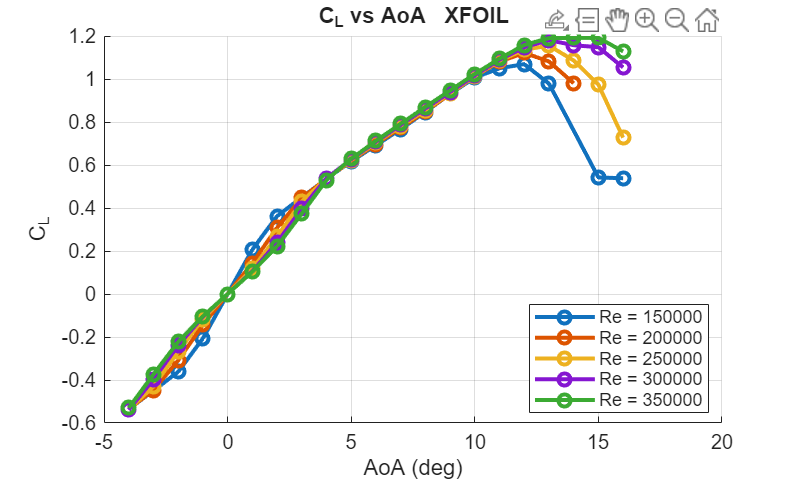

% plot_xfoil_three_figs_relegend.m
% Read XFOIL output files and plot CL, CD, CM vs angle of attack (AoA)
xfoilFiles = [ ...
    "C:\Users\marke\Desktop\XFOIL6.99\naca0012_150k_v15", ...
    "C:\Users\marke\Desktop\XFOIL6.99\naca0012_200k_v20", ...
    "C:\Users\marke\Desktop\XFOIL6.99\naca0012_250k_v25", ...
    "C:\Users\marke\Desktop\XFOIL6.99\naca0012_300k_v30", ...
    "C:\Users\marke\Desktop\XFOIL6.99\naca0012_350k_v35" ...
];

% Reynolds numbers to display in the legend 
Re_vals = [150e3, 200e3, 250e3, 300e3, 350e3];
labels = "Re = " + string(Re_vals);   % string array of labels

n = numel(xfoilFiles);
if numel(labels) ~= n, error('Number of labels must match number of files.'); end

colors = lines(n);

% Figure 1: C_L vs AoA
figure('Name','C_L vs AoA'); hold on; grid on;
xlabel('AoA (deg)'); ylabel('C_L'); title('C_L vs AoA   XFOIL');

% Figure 2: C_D vs AoA
figure('Name','C_D vs AoA'); hold on; grid on;
xlabel('AoA (deg)'); ylabel('C_D'); title('C_D vs AoA   XFOIL');

% Figure 3: C_m vs AoA
figure('Name','C_m vs AoA'); hold on; grid on;
xlabel('AoA (deg)'); ylabel('C_m'); title('C_m vs AoA   XFOIL');

for i = 1:n
    fname = xfoilFiles(i);
    try
        [alpha, CL, CD, CM] = parseXfoilAll(fname);
        alpha = alpha(:); CL = CL(:); CD = CD(:); CM = CM(:);

        % Add to CL figure
        figure(findobj('Type','figure','Name','C_L vs AoA')); hold on;
        plot(alpha, CL, '-o', 'Color', colors(i,:), 'MarkerSize',6, 'LineWidth', 2, 'DisplayName', labels(i));

        % Add to CD figure
        figure(findobj('Type','figure','Name','C_D vs AoA')); hold on;
        plot(alpha, CD, '-s', 'Color', colors(i,:), 'MarkerSize',6, 'LineWidth', 2, 'DisplayName', labels(i));

        % Add to CM figure
        figure(findobj('Type','figure','Name','C_m vs AoA')); hold on;
        plot(alpha, CM, '-^', 'Color', colors(i,:), 'MarkerSize',6, 'LineWidth', 2, 'DisplayName', labels(i));
    catch ME
        warning('Failed to parse %s: %s', fname, ME.message);
    end
end

% Add legends 
f1 = findobj('Type','figure','Name','C_L vs AoA');
if ~isempty(f1), figure(f1); legend('Location','best'); end

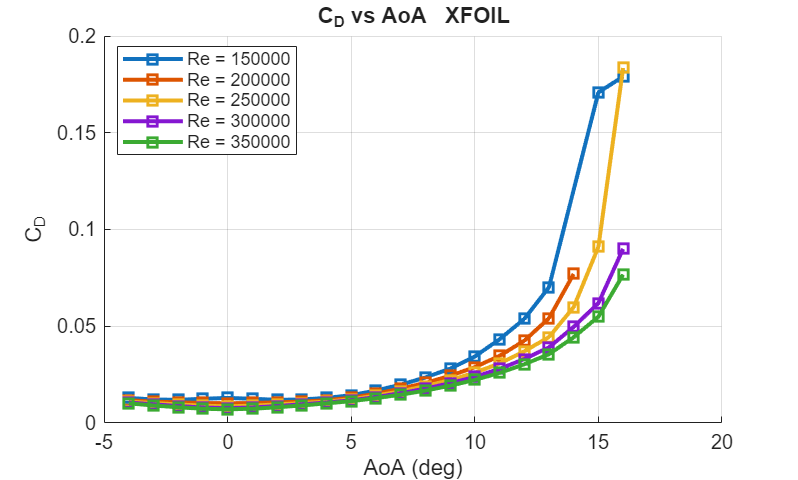

f2 = findobj('Type','figure','Name','C_D vs AoA');
if ~isempty(f2), figure(f2); legend('Location','best'); end

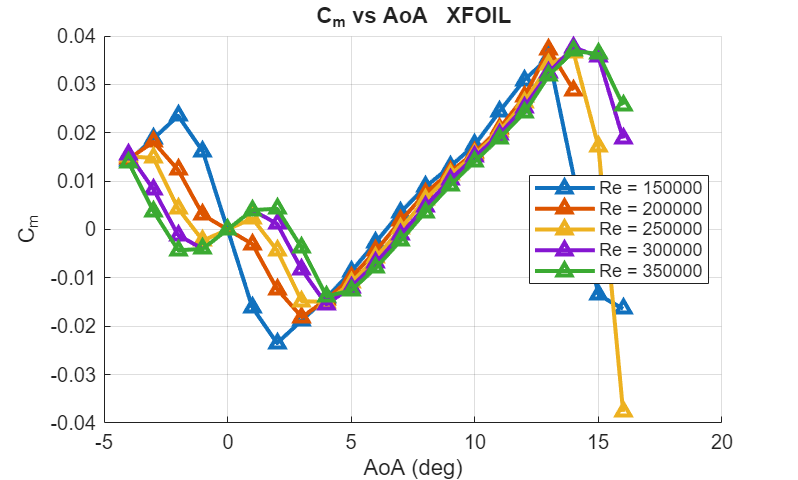

f3 = findobj('Type','figure','Name','C_m vs AoA');
if ~isempty(f3), figure(f3); legend('Location','best'); end


% ----------------------
function [alpha, CL, CD, CM] = parseXfoilAll(fname)
   
    try
        T = readtable(fname,'FileType','text','PreserveVariableNames',true);
        vars = lower(T.Properties.VariableNames);
        idxA = find(contains(vars,{'alpha','aoa','angle'}),1);
        idxCL = find(contains(vars,{'cl','c_l','lift'}),1);
        idxCD = find(contains(vars,{'cd','c_d','drag'}),1);
        idxCM = find(contains(vars,{'cm','c_m','moment'}),1);

        numericCols = varfun(@isnumeric, T, 'OutputFormat','uniform');
        numIdx = find(numericCols);

        if isempty(idxA) || isempty(idxCL) || isempty(idxCD) || isempty(idxCM)
            if numel(numIdx) >= 4
                idxA = choose(idxA, numIdx(1));
                idxCL = choose(idxCL, numIdx(2));
                idxCD = choose(idxCD, numIdx(3));
                idxCM = choose(idxCM, numIdx(4));
            else
                error('Missing expected columns and not enough numeric columns.');
            end
        end

        alpha = T{:, idxA};
        CL = T{:, idxCL};
        CD = T{:, idxCD};
        CM = T{:, idxCM};
        return;
    catch
       
        fid = fopen(fname,'r');
        if fid < 0, error('Cannot open file %s', fname); end
        alpha = []; CL = []; CD = []; CM = [];
        while ~feof(fid)
            ln = strtrim(fgetl(fid));
            if isempty(ln), continue; end
            toks = regexp(ln,'\s+','split');
            nums = str2double(toks);
            if all(isnan(nums)), continue; end
            nums = nums(~isnan(nums));
            if numel(nums) >= 4
                alpha(end+1,1) = nums(1); 
                CL(end+1,1)    = nums(2); 
                CD(end+1,1)    = nums(3);
                CM(end+1,1)    = nums(4); 
            end
        end
        fclose(fid);
        if isempty(alpha), error('No numeric data found in %s', fname); end
    end
end

function out = choose(prev, alt)
    if ~isempty(prev), out = prev; else out = alt; end
end
